# EXERCISE #5 Compare Throughput of Various Multi-Link Operations(MLO) modes and Non-MLO mode

Copyright 2024-2025 The MathWorks, Inc

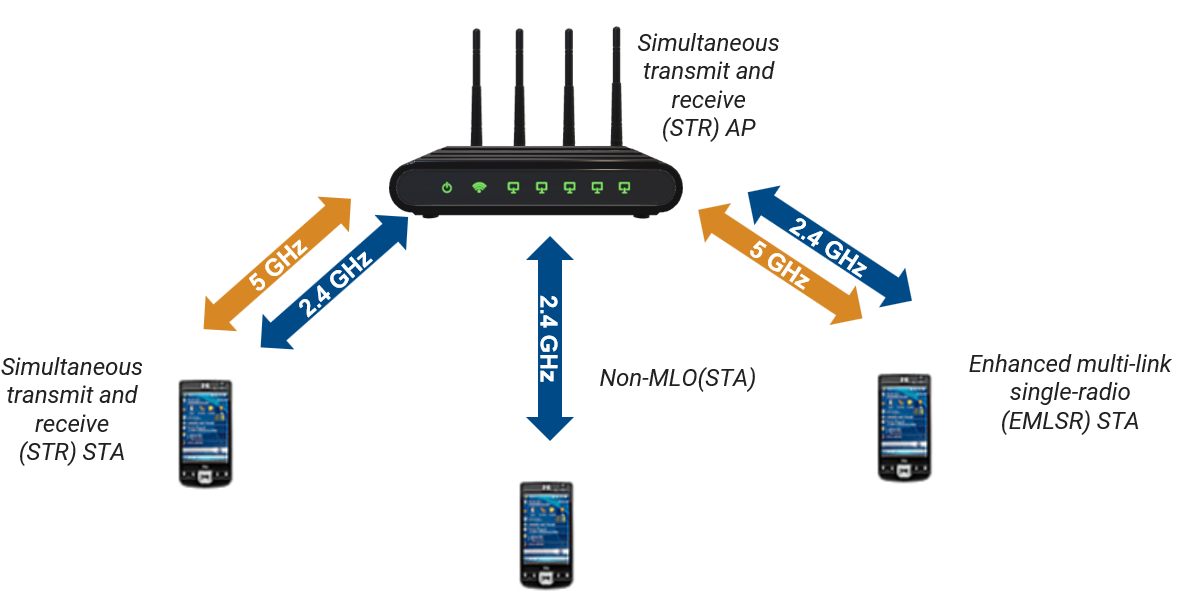

WLAN Network with one STR AP, STR STA, EMLSR STA, and Non MLO STA 

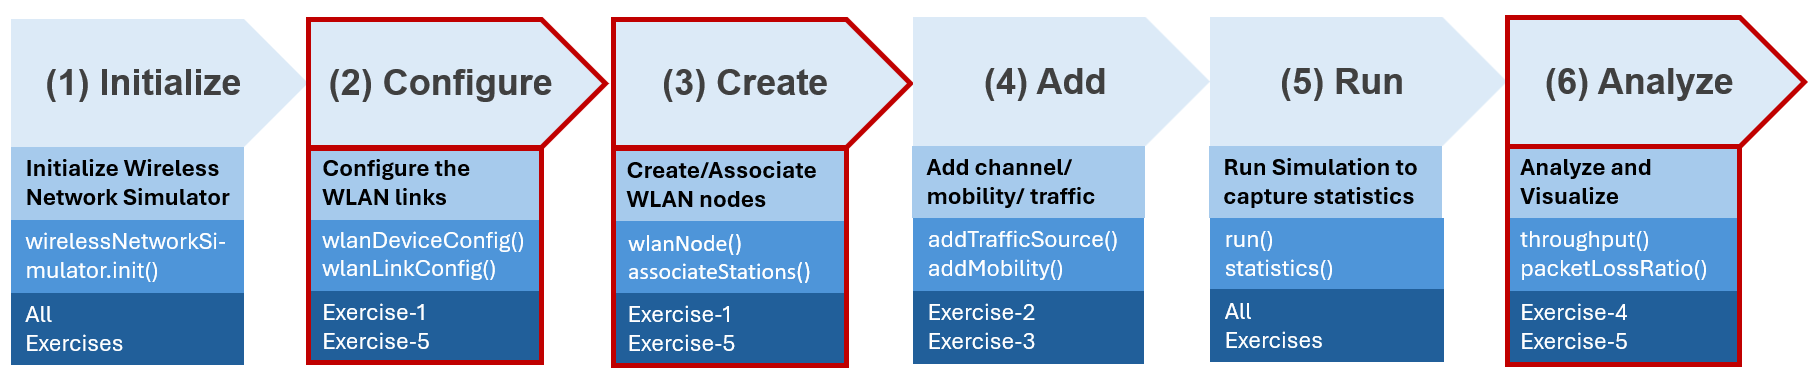

Workflow to perform WLAN Network Modeling 

Set the seed for the random number generator to `1`. The seed value controls the pattern of random number generation. The random number generated by the seed value impacts several processes within the simulation, including backoff counter selection at the MAC layer and predicting packet reception success at the physical layer.

Copyright 2024-2025 The MathWorks, Inc

% Set seed of random number generator for reproducible results
rng(1,"combRecursive");
% Set simulation time as 1 Sec
simulationTime = 1;
% Create wireless network simulator
networkSimulator = wirelessNetworkSimulator.init;

%Define positions of nodes
AP_pos  = [0,0,0];
STR_STA_pos = [10,0,0];
EMLSR_STA_pos = [0,10,0];
NON_MLO_STA_pos = [0,0,10];

% Band and channel values for each link
bandAndChannel = [2.4 1;5 36];

Create the AP MLD node, STR STA MLD node, EMLSR STA MLD node

#### 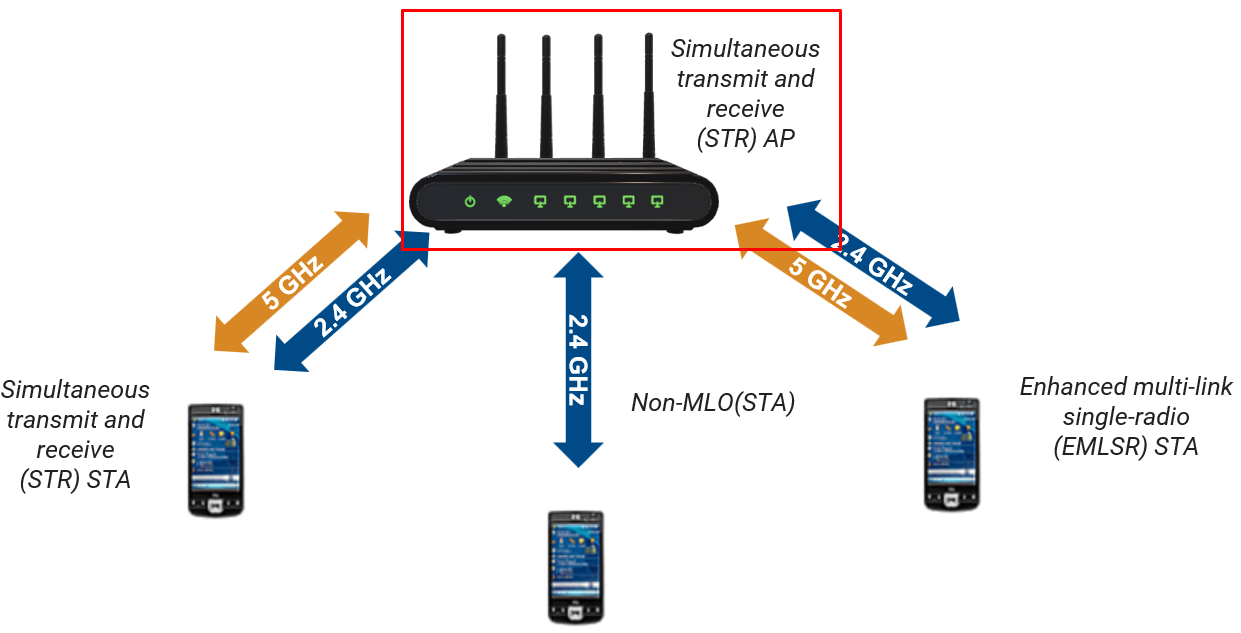

#### Create an STR AP

apLinkCfg = wlanLinkConfig("BandAndChannel",bandAndChannel,...
    "NumTransmitAntennas", 2, ...
    "NumSpaceTimeStreams", 2, ...
    "MCS",3);

apMLDCfg = wlanMultilinkDeviceConfig("Mode","AP", ...
    "LinkConfig",apLinkCfg);

apNode = wlanNode("Position",AP_pos, ...
    "Name","AP", ...
    "DeviceConfig",apMLDCfg);

#### 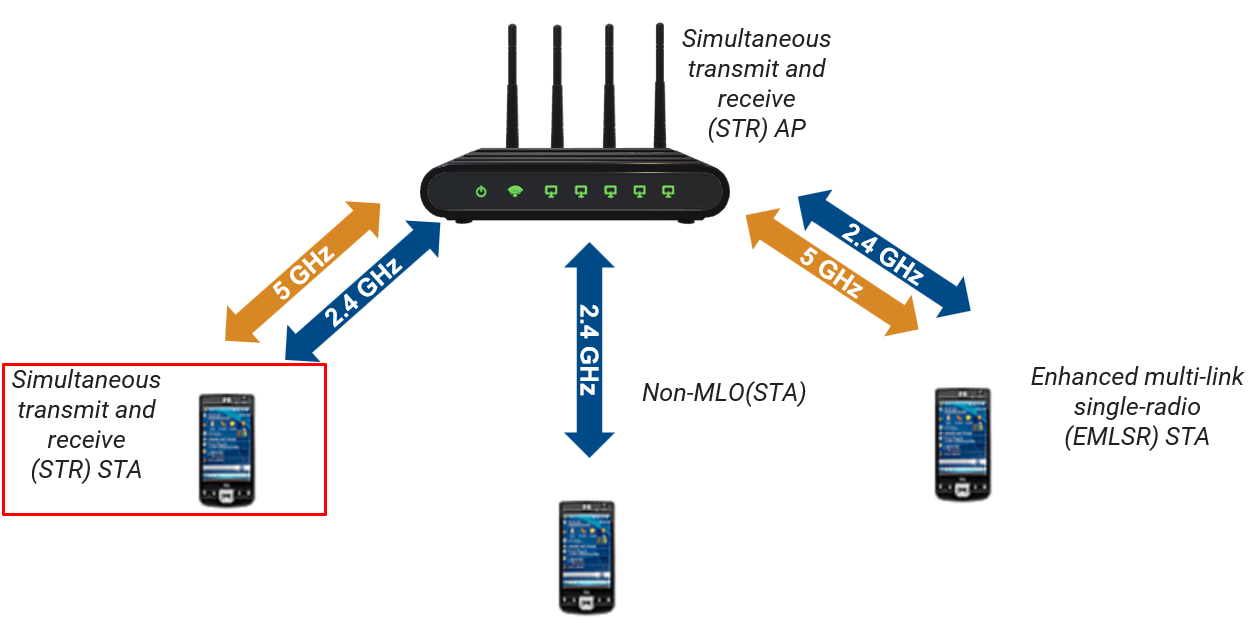

#### Create an STR STA


staSTRLinkCfg = wlanLinkConfig("BandAndChannel",bandAndChannel,...
    "NumTransmitAntennas", 2, ...
    "NumSpaceTimeStreams", 2, ...
    "MCS",3);

staSTRMLDCfg = wlanMultilinkDeviceConfig("Mode","STA", ...
    "LinkConfig",staSTRLinkCfg);

staNodes(1) = wlanNode("Position",STR_STA_pos, ...
    "Name","STR STA", ...
    "DeviceConfig",staSTRMLDCfg);

# 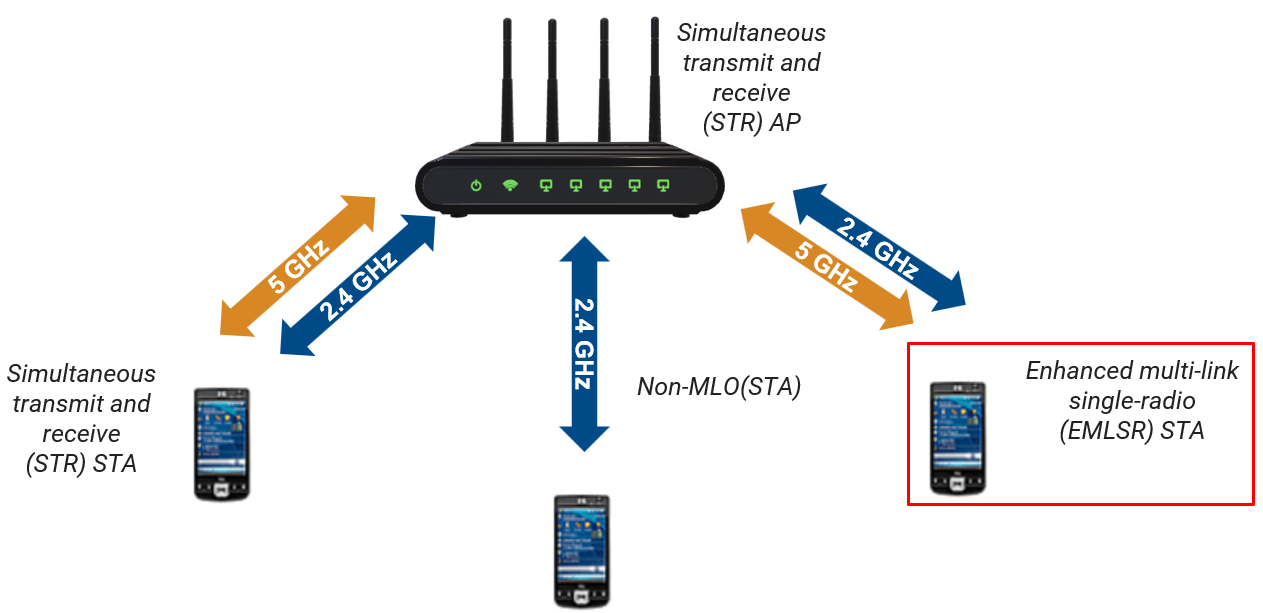

# Task #1/4 Create an link configuration of EMLSR STA 

% Create an EMLSR STA 
% Use wlanLinkConfig() function to configure EMLSR STA link
% Write EMLSR STA link configuration in a variable named "staEMLSRLinkCfg"
% Hint: Type "doc wlanLinkConfig" in the MATLAB Command Window, and see the "Syntax" section.
% "BandAndChannel",bandAndChannel
% "NumTransmitAntennas",1
% "NumSpaceTimeStreams",1
% "MCS",3

% Write code here
% staEMLSRLinkCfg =


# Task #2/4 Create an device configuration of EMLSR STA

% Use wlanMultilinkDeviceConfig() function to Configure EMLSR STA 
% Write STR STA device configuration in a variable named "staEMLSRMLDCfg"
% Hint: Type "doc wlanMultilinkDeviceConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% "Mode","STA"
% "LinkConfig",staEMLSRLinkCfg
% "EnhancedMultilinkMode","EMLSR"

% Write code here
% staEMLSRMLDCfg =

# Task #3/4 Create an EMLSR STA

% Use wlanNode() function to create EMLSR STA 
% Write EMLSR STA node in a variable named "staNodes(2)"
% Note : use the following values to start with
% "Position",EMLSR_STA_pos
% "Name","EMLSR STA"
% "DeviceConfig",staEMLSRMLDCfg

### [Help on creating WLAN node ](https://www.mathworks.com/help/wlan/ref/wlannode.html)

% Write code here
% staNodes(2) =

#### 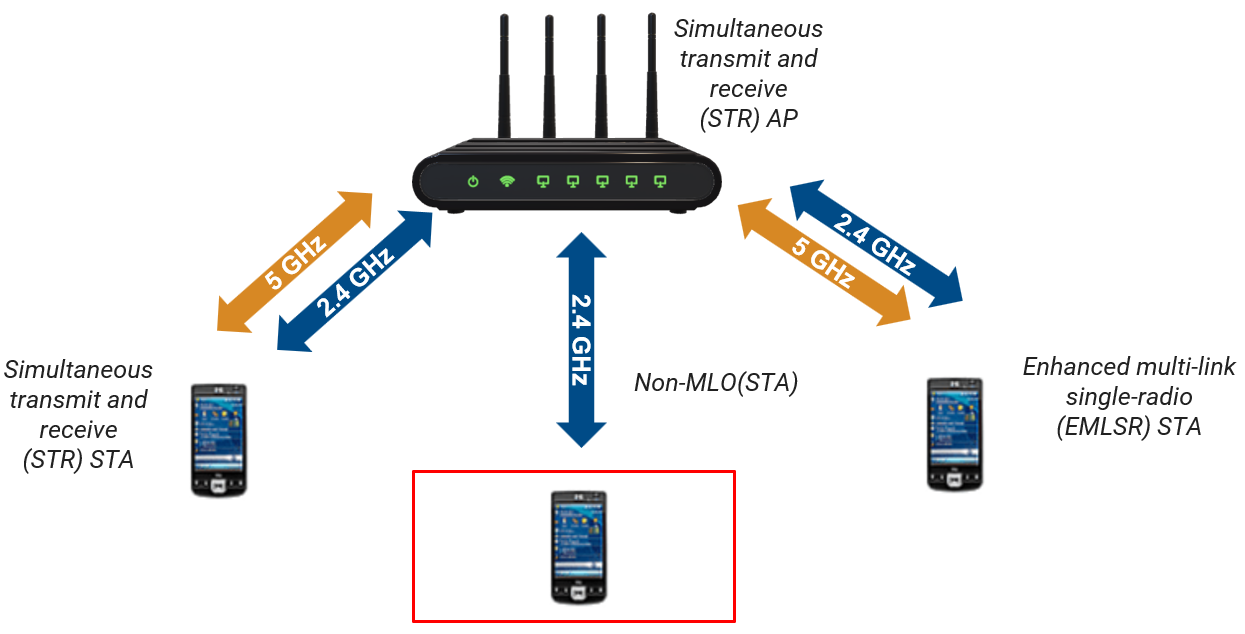

#### Create an Non-MLO STA


staDeviceConfig = wlanDeviceConfig("Mode","STA","BandAndChannel",bandAndChannel(1,:),...
    "NumTransmitAntennas",2, ...
    "NumSpaceTimeStreams",2, ...
    "MCS",3, ...
    "TransmissionFormat","EHT-SU");

staNodes(3) = wlanNode("Position",NON_MLO_STA_pos, ...
    "Name","Non-MLD STA", ...
    "DeviceConfig",staDeviceConfig);
nodes = [apNode staNodes];

### Create the Network 

associateStations(apNode,staNodes,FullBufferTraffic="UL");

### Add the Channel  

hSLSTGaxMultiFrequencySystemChannel is a channel model implemented for use in WLAN system-level simulations. This channel is based on TGax simulation scenarios document (doc.: IEEE 802.11-14/0980r16). It models NLOS, Model-D delay profile, freespace pathloss based off of doc.: IEEE 802.11-14/0980r16.

channel = hSLSTGaxMultiFrequencySystemChannel(nodes);
addChannelModel(networkSimulator,channel.ChannelFcn);

% Add the network to networkSimulator 
addNodes(networkSimulator,nodes);
% Enable packet visualization 
enablePacketVisualization = false;
if enablePacketVisualization
    packetVisObj = hPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=false);
end

% Create node performance visualization object
perfViewerObj = hPerformanceViewer(nodes,simulationTime);

% Run the simulation
run(networkSimulator,simulationTime);

% Calculate throughput at STAs
staThroughputs = throughput(perfViewerObj,[staNodes(:).ID]);
apPacketLossRatio = packetLossRatio(perfViewerObj,[staNodes(:).ID])
staAverageReceiveLatency = averageReceiveLatency(perfViewerObj,[staNodes(:).ID])

## Plot the STA throughputs as a bar graph

fig = figure;
matlab.graphics.internal.themes.figureUseDesktopTheme(fig);
% Names of the bars
modes = ["MLO-STR" "MLO-EMLSR" "Non-MLO"];
% Plot a bar graph specifying the width of bar (40% of available bar width)
% and face color
b = bar(modes,staThroughputs,0.4,'FaceColor','flat');
% RGB triplets for second and third bars
b.CData(2,:) = [0.8 0.3 0.1];
b.CData(3,:) = [0.9 0.6 0.1];
title("UL Throughput at STAs Operating in Different MLO Modes");
ylabel("MAC Throughput (Mbps)");

# Task #4/4 Identify the count of packets transmitted from each link of EMLSR STA 

% Create a variable names stats
% Use function call statistics(staNodes, "all"); 

### [Help on statistics](https://www.mathworks.com/help/wlan/ref/wlannode.statistics.html)

% Write code here
% stats =

**Suggested Experiment:**

- **For the EMLSR STA:**

- **Set the number of antennas to 2.**

- **Set the number of spatial streams to 2.**

- **Update the STR AP link configuration to align with these new settings.**

- **Compare the performance results before and after making these changes.**

*Copyright 2024 The MathWorks, Inc.*